# `專題二`

1.嘗試調整mfcc_v2.m中的參數sample_rate、frame_time、frame_move_time，說明mfc檔對於聲音擷取特徵的數值變化和意義

**參數說明：**

lsample_rate：一段音訊的取樣頻率 (單位：HZ)

lframe_time：一個音框的取樣時間長度 (單位：毫秒)

lframe_move_time：一個音框與取下一個音框重疊的時間 (單位：毫秒)

% 呼叫 mfcc_v2.m 改ample_rate、frame_time、frame_move_time
% 初始：sample_rate=44100, frame_time=30, frame_move_time=15
% 只更改sample_rate=16000(取樣頻率變小)
% 只更改sample_rate=80000(取樣頻率變大)
% 只更改frame_time=100, frame_move_time=50
% 只更改frame_time=10, frame_move_time=5


2.完成下表，嘗試調整K值設為3 ,5 ,7奇數，設定為多少時準確值較佳? 

% 先跑labeling
path = 'E:/2020 DSP專題二/Train_Test/normal_tain';% 輸入mfc檔路徑資料夾
 cd(path)                                 % 進入選取的資料夾
 file=dir([path '\*.mfc']);
 Data= [];
for i = 1:length(file)
     cep_data = load(file(i).name);            % 讀入每個mfc檔
     number_person(i,:) = length(cep_data(:,1));  % 每個mfc檔的長度
 	Data= [Data;cep_data];                 % 與上個mfc檔進行串聯
 end
 lable=zeros(length(Data),1)
 Data_normal_train=[lable Data]
 
 
 path = 'E:/2020 DSP專題二/Train_Test/im_train';% 輸入mfc檔路徑資料夾
 cd(path)                                 % 進入選取的資料夾
 file=dir([path '\*.mfc']);
 Data= [];
 for i = 1:length(file)
     cep_data = load(file(i).name);            % 讀入每個mfc檔
     number_person(i,:) = length(cep_data(:,1));  % 每個mfc檔的長度
 	Data= [Data;cep_data];                 % 與上個mfc檔進行串聯
 end
 lable=ones(length(Data),1)
 Data_im_train=[lable Data]
 
 Data_train=[Data_normal_train;Data_im_train]
 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 path = 'E:/2020 DSP專題二/Train_Test/normal_test';% 輸入mfc檔路徑資料夾
 cd(path)                                 % 進入選取的資料夾
 file=dir([path '\*.mfc']);
 Data= [];
 for i = 1:length(file)
     cep_data = load(file(i).name);            % 讀入每個mfc檔
     number_person_normal(i,:) = length(cep_data(:,1));  % 每個mfc檔的長度
 	Data= [Data;cep_data];                 % 與上個mfc檔進行串聯
 end
 lable=zeros(length(Data),1)
 Data_normal_test=[lable Data]
 
 
 path = 'E:/2020 DSP專題二/Train_Test/im_test';% 輸入im_CYST_test檔路徑資料夾
 cd(path)                                 % 進入選取的資料夾
 file=dir([path '\*.mfc']);
 Data= [];
 for i = 1:length(file)
     cep_data = load(file(i).name);            % 讀入每個mfc檔
     number_person_im(i,:) = length(cep_data(:,1));  % 每個mfc檔的長度
 	Data= [Data;cep_data];                 % 與上個mfc檔進行串聯
 end
 lable=ones(length(Data),1)
 Data_im_test=[lable Data]
 
 Data_test=[Data_normal_test;Data_im_test]
 Person_test=[number_person_normal;number_person_im]

% Frame
tested = trainedModel.predictFcn(Data_test(:,2:27)); % k=1; 
True_frame=0;

for i=1:21785                                   % 總音框數
    if Data_test(i,1)==tested(i,1);             % 檢查預測是否正確
       True_frame=True_frame+1;                 % 若正確,True_frame+1
    end
end
Frame=(True_frame/21785)*100;                   % 計算百分比 
fprintf('k=1：%2.2f %%',Frame);                 % 顯示百分比

k=1：79.84 %


% Person
last_frame=0;                                   % 初始化
Correct=0;                                      % 初始化
True_person(1:10,1)=0,True_person(11:20,1)=1;   % 正解

True_person =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for person=1:20                                 % 總共20人
   count=last_frame+1;                          % count從上一輪結束開始算
   last_frame=last_frame+Person_test(person,1); % 得知計算到何處為一個人的
   
   if sum(tested(count:last_frame,1))>Person_test(person)/2 % 若有病音框>一半
      predict(person,1)=1;                      % 若大於一半,predict存1
   else
      predict(person,1)=0;                      % 若小於一半,predict存0
   end
   
   if True_person(person,1)==predict(person,1)  % 比較預測人跟實際人是否相同
       Correct=Correct+1;                       % 若相同,Correct+1
   end
end
Correct=(Correct/20)*100;                       % 計算百分比
fprintf('k=1：%d %%',Correct);                  % 顯示百分比

k=1：80 %

3.嘗試畫出生病與正常聲音（各挑選一個）的頻譜圖和波形圖（參考LAB6），說明之間的差異？

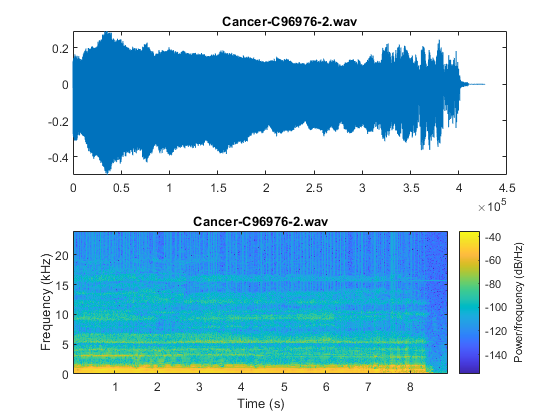

% Cancer
[y,fs]=audioread('C96976-2.wav');
figure;
subplot(2,1,1);
plot(y);
title('Cancer-C96976-2.wav');
subplot(2,1,2);
spectrogram(y(:,1), 1024, 1000, [], fs, 'yaxis')
title('Cancer-C96976-2.wav');

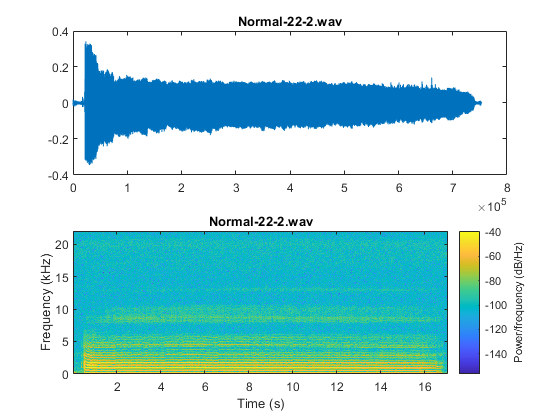


% Normaml
[y,fs]=audioread('22-2.wav');
figure;
subplot(2,1,1);
plot(y);
title('Normal-22-2.wav');
subplot(2,1,2);
spectrogram(y(:,1), 1024, 1000, [], fs, 'yaxis')
title('Normal-22-2.wav');

4.使用實驗三、四預測在資料夾other中的10個語音檔

path = 'E:/2020 DSP專題二/MFCC/other';            % 輸入other的mfc檔路徑資料夾
 cd(path)                                        % 進入選取的資料夾
 file=dir([path '\*.mfc']);
 Data= [];
for i = 1:length(file)
     cep_data = load(file(i).name);              % 讀入每個mfc檔
     Number_other(i,:) = length(cep_data(:,1));  % 每個mfc檔的長度
 	Data= [Data;cep_data];                       % 與上個mfc檔進行串聯
end
 Data_other=Data

Data_other =   -13.2490    1.8867   -4.1099    1.4929   -2.5678    1.0354   -1.3761    1.0234   -1.3878    1.1668   -0.9039    0.4716  -11.2772   -3.3957    0.3896   -0.6295   -0.1314   -1.0130    0.4839    0.6028    1.5120    0.7327    1.7244    0.7957    0.9796   -4.2268
  -27.5290    3.4726   -5.2218    3.4265   -4.8621    8.4822    7.7274   11.7833    9.5122   17.1558    8.2734    8.8284  -30.1638   -3.2419    0.5355   -0.2819    0.1241   -0.8432    1.1634    1.3640    1.4956    0.2811    0.9298    0.5009    0.6611   -4.1990
  -29.2098    5.0084   -7.6018    1.1186   -2.3884    5.1097   -1.6504   -0.0018   -1.7400    6.2383    1.4989    4.8448  -31.5964   -2.6233    0.5033    0.0256    0.9521   -0.3472    0.5048    0.5565    1.4210    0.1437    0.4334    0.4615    0.4311   -3.4947
  -29.5421    2.9132   -7.2863   -0.1284  -11.3773    0.3535    1.3982   12.2318    2.0523    8.5509    1.8615    3.9138  -30.8857   -1.2145    0.6278    0.2282    0.7629   -0.5428   -0.0532    0.1386    

 
tested = trainedModel7.predictFcn(Data_other(:,1:26));

% Person
last_frame=0;                                   % 初始化
Correct=0;                                      % 初始化
for person=1:10                                 % 總共10人
   count=last_frame+1;                          % count從上一輪結束開始算
   last_frame=last_frame+Number_other(person,1); % 得知計算到何處為一個人的
   
   if sum(tested(count:last_frame,1))>Number_other(person)/2 % 若有病音框>一半
      predict(person,1)=1;                      % 若大於一半,predict存1
   else
      predict(person,1)=0;                      % 若小於一半,predict存0
   end
end
predict

predict =      0
     1
     0
     0
     1
     0
     0
     1
     0
     1
